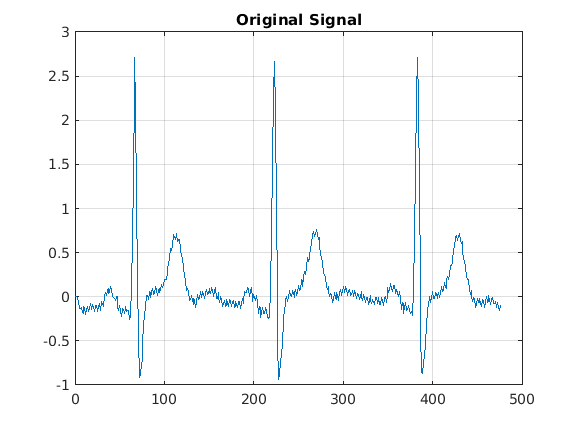

close all;clear;clc;
sig=load('ecg_60hz_200.dat');
sig1 = sig + awgn(sig,10);
N=length(sig);
fs=200;
t=[0:N-1]/fs;
figure(1);plot(sig)
grid on
title('Original Signal')
grid on

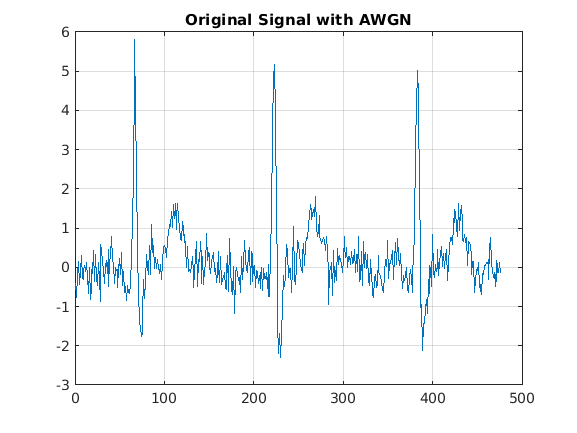

figure(1);plot(sig1)
grid on
title('Original Signal with AWGN')

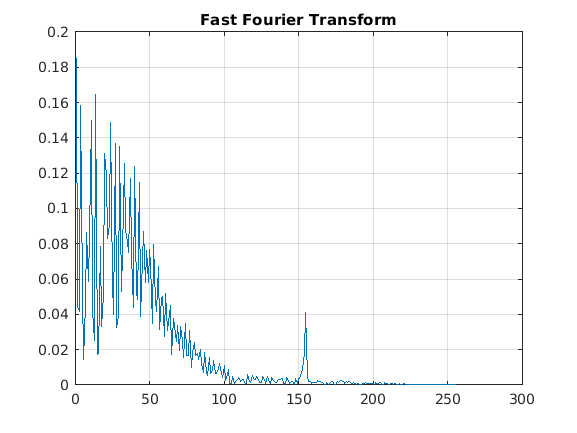

%  sig = data 
%  fs = sampling rate / frequency (Hz)
NFFT = 2 ^ nextpow2(length(sig));   
Y = fft(double(sig), NFFT) / length(sig);
f = (double(fs) / 2 * linspace(0, 500, NFFT / 2))'; 
% f adalah vektor yang mengandung frekuensi dalam Hz
amp = 2 * abs(Y(1:(NFFT / 2))); 
% amp adalah Vector yang mengandung corresponding amplitudes
figure(1);plot(amp)
grid on
title('Fast Fourier Transform')

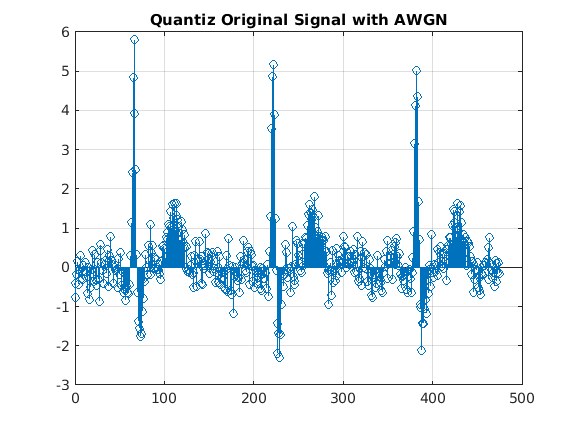

bd = 8;
y = sig1;
N_samples = length(y);
n = 0:(length(y)/N_samples)+0.00001:N_samples;
Xq_out = zeros(1,N_samples);
index = zeros(1,N_samples);
    sig1_max = round(max(sig1));
    sig1_min = round(min(sig1));
   del = (sig1_max-sig1_min)/2.^bd;
   V_max = sig1_max - del/2;
   V_min = sig1_min + del/2;
   
   for i=V_min:del:V_max
       for j=1:N_samples
           if(((i-del/2)<y(j)) && (y(j)<(i+del/2)))
               Xq_out(j) = i;
               index(j) = round((y(j)-V_min)/del);
           end
       end
   end


figure(1); stem(n,y);
grid on
title('Quantiz Original Signal with AWGN')

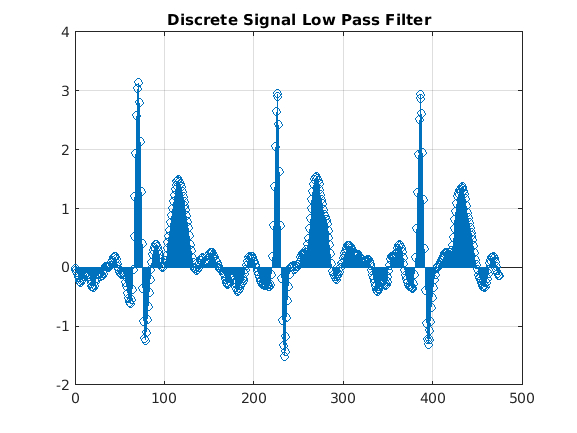

b=1/32*[1 0 0 0 0 0 -2 0 0 0 0 0 1];
a=[1 -2 1];
sigL=filter(b,a,y);
figure(1); stem(n, sigL);
grid on
title('Discrete Signal Low Pass Filter')

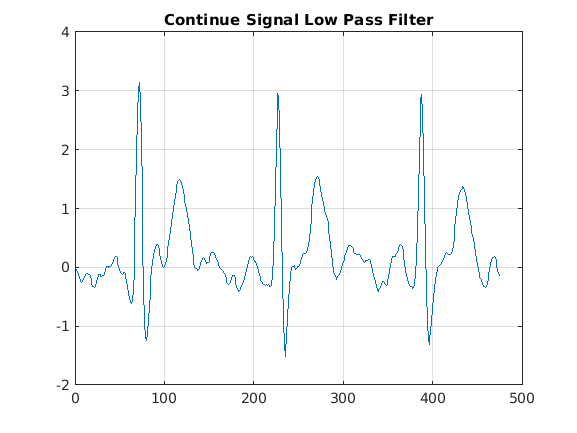

b=1/32*[1 0 0 0 0 0 -2 0 0 0 0 0 1];
a=[1 -2 1];
sigLPF=filter(b,a,y);
figure(1); plot(sigLPF);
grid on
title('Continue Signal Low Pass Filter')

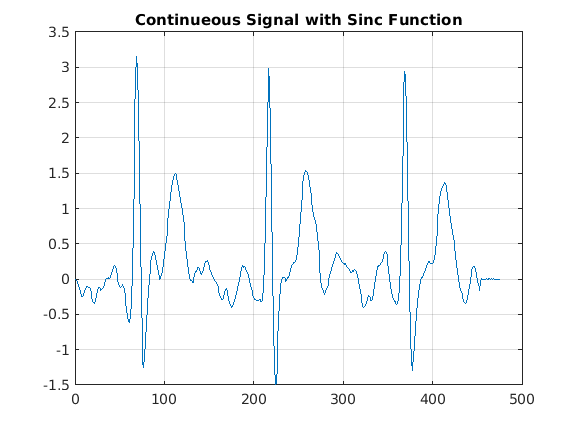

t2 = 1:length(y);
ts = linspace(0, 500, N_samples);
[Ts,T] = ndgrid(ts,t2);
yp = sinc((Ts-T))*sigLPF;

figure(1); plot(yp);
grid on
title('Continueous Signal with Sinc Function')

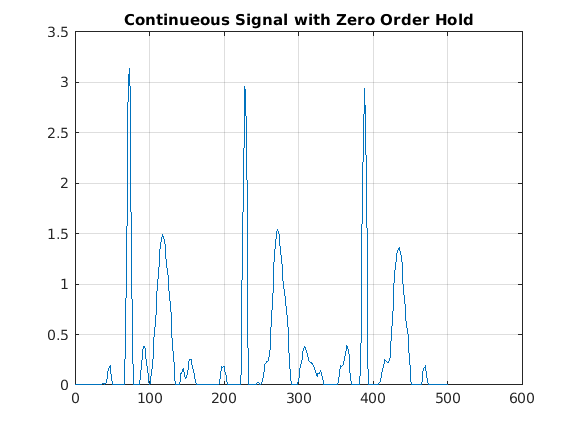

zoh = interp1(sigLPF,0:500,'nearest',"extrap");
zoh(zoh<0) = [0];
zoh(zoh<-0.05) = [0.05];
zoh(zoh<=-0.1) = [0.1];
plot(zoh);
grid on
title('Continueous Signal with Zero Order Hold')

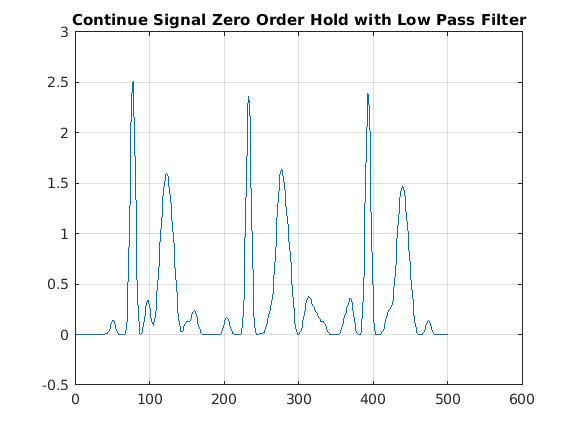

b=1/32*[1 0 0 0 0 0 -2 0 0 0 0 0 1];
a=[1 -2 1];
zoh_lpf=filter(b,a,zoh);
figure(1); plot(zoh_lpf);
grid on
title('Continue Signal Zero Order Hold with Low Pass Filter')

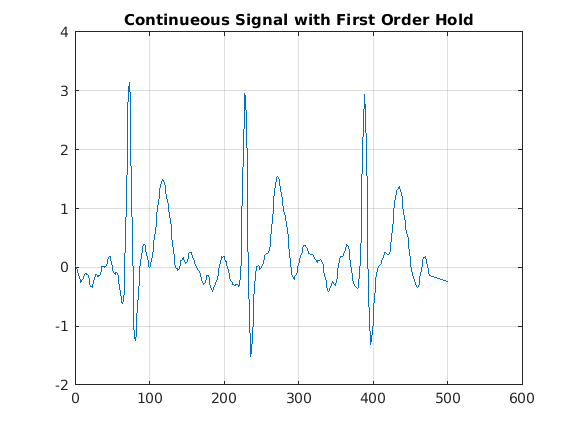


g = interp1(sigLPF,0:500,"linear","extrap");
figure(1);plot(g)
grid on
title("Continueous Signal with First Order Hold")

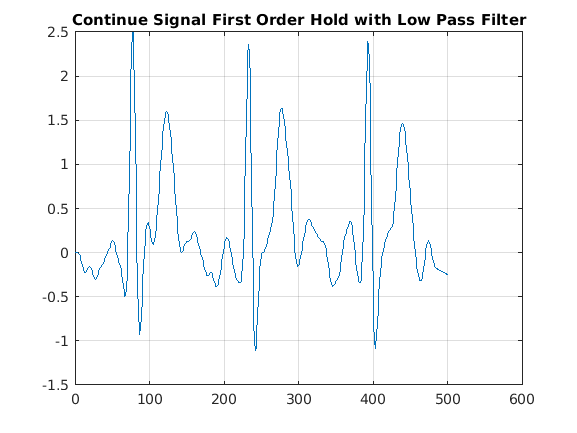

b=1/32*[1 0 0 0 0 0 -2 0 0 0 0 0 1];
a=[1 -2 1];
g_lpf=filter(b,a,g);
figure(1); plot(g_lpf);
grid on
title('Continue Signal First Order Hold with Low Pass Filter')